# Final Project - Jackson H, Graham S, Joshua W

clear;
clc;

## Importing Images

img_dir = dir('*.png');
img_names = {img_dir.name};
img_folder = {img_dir.folder};
imgs = cell(size(img_names,2),2);
imgs(:,1) = regexprep(img_names, '.png', '');

% Import and store rgb and grayscale versions on each image
for i = 1:numel(img_names)
    temp = imread(strcat(img_folder{i},'\',img_names{i}));
    imgs{i,2} = temp(280+1:end,520+1:end,:); % Crop image to areas that only contain sheep
    imgs{i,3} = rgb2gray(imgs{i,2}); % save grayscale version of original image
end

clear img_dir img_folder img_names

## Threshold Enhanced Images

% Look at histograms of images to find good threshold value
%
% for i = 1:size(imgs,1)
%     figure;
%     histogram(imgs{i,3});
% end
%
% Found 140 to be a good point to choose as threshold value

thresh = 140;
for i = 1:size(imgs,1)
    imgs{i,4} = imgs{i,3}>=thresh; % creates logical matrix from threshold value
%     figure;
%     imshow(imgs{i,4}); % displays and saves thresholded images
%     title(strcat("Threshold Image For ",imgs{i,1}));
%     saveas(gcf,strcat("threshold_",imgs{i,1},".jpg"));
end

## Structure Elements

% Due to the fact that sheep exist in the image at several different sizes
% and orientations there is no one structure element to accurately identify
% each individual sheep. After analyzing the threshold images we found that
% a large majority of sheep had a width of at least 3 pixels. This is why
% we made our structure element a 3x3 square so no sheep will be lost
% regardless of their orientation. We then close the image with a smaller
% 2x2 square to fill in any gaps giving sheep a more uniform shape.

rec = strel('rectangle',[3,3]).Neighborhood;
for i = 1:size(imgs,1)
    imgs{i,5} = imopen(imgs{i,4},rec); % Opens with larger structure element
    imgs{i,5} = imclose(imgs{i,5},rec); % Closes with smaller element
%     figure;
%     imshow(imgs{i,5});
%     title(strcat("Opened Image For ",imgs{i,1}))
end

## Obtain Image Heatmaps

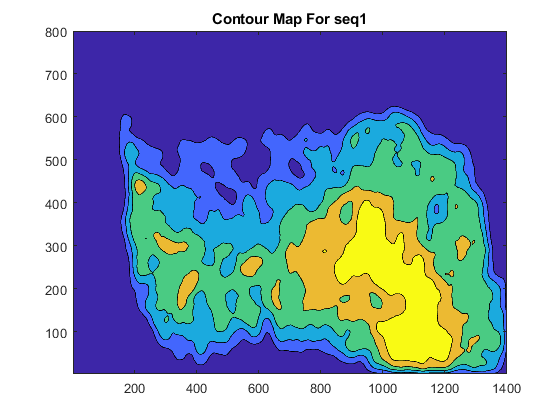

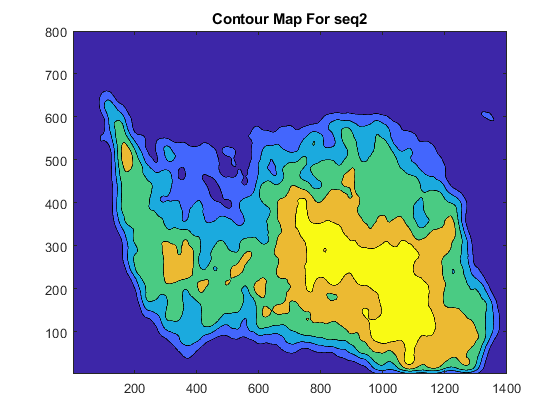

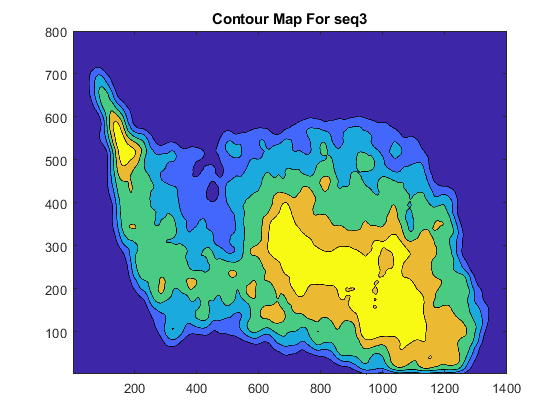

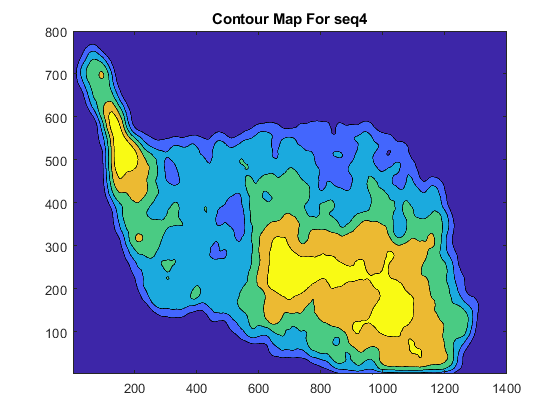

% Applying edge enhancement filters as they will help to increase the
% emphasis placed on the sheep in the image without amplifying any of the
% noise or other elements within the image.

Hx = [-1 -2 -1; 0 0 0; 1 2 1];  % x gradient filter
Hy = [-1 0 1; -2 0 2; -1 0 1];  % y gradient filter

% Create averaging filter that is big enough to fully cover several
% sheep. We use two averaging filters to obtain our heat maps. The 
% first is a 50x50 filter which calculated our densities and the second 
% is a 25x25 filter which reduces the noise and jitter in the contour map.

H25 = ones(25)/(25^2);
H50 = ones(50)/(50^2);

%Sharpen images to better define boundaries of sheep
for i = 1:size(imgs,1)
    edgx = conv2(imgs{i,3},Hx,'same'); % calculate x-component of edges
    edgy = conv2(imgs{i,3},Hy,'same'); % calculate y-component of edges
    edge = sqrt(edgx.^2+edgy.^2); % calculate magnitude of edges
    edge = uint8(rescale(edge,0,255)); % rescale edge values to fill entire space
    edge = imgs{i,3}+edge >= 130; % add edges onto grayscale image
    temp = conv2(edge,H50,'same'); % use larger filter to get density estimate
    temp = conv2(temp,H25,'same'); % use smaller filter to reduce noise
    figure;
    contourf(flip(temp,1),5); % use filled contour to show high/low density areas
    title(strcat("Contour Map For ",imgs{i,1}));
%     saveas(gcf,strcat("contour_",imgs{i,1},".jpg"));
end


clear edgx edgy edge temp

## Determining General Velocities

% We begin by calculating the center of mass of the entire herd. 
% This is done by totaling the x and y values of every nonzero pixel and
% then dividing by the total number of nonzero pixels.
%
% By monitoring the location of the center of mass we can get an average
% velocity estimate across the entire sheep herd.

for k = 1:size(imgs)
    sumX = 0;
    sumY = 0;
    pix = 0;
    [m,n] = size(imgs{k,5});
    for i = 1:m
        for j = 1:n
            if (imgs{k,5}(i,j)==1)
                pix = pix+1;
                sumX = sumX + i;
                sumY = sumY + j;
            end
        end
    end
    tot(k,1) = sumX/pix;
    tot(k,2) = sumY/pix;
end

% Calculate x and y displacements from frame to frame
disp21y = (tot(1,1)-tot(2,1));
disp21x = (tot(1,2)-tot(2,2));
disp32y = (tot(2,1)-tot(3,1));
disp32x = (tot(2,2)-tot(3,2));
disp43y = (tot(3,1)-tot(4,1));
disp43x = (tot(3,2)-tot(4,2));

% Calculate displacement magnitudes using x and y components
disp21 = sqrt(disp21x^2+disp21y^2);
disp32 = sqrt(disp32x^2+disp32y^2);
disp43 = sqrt(disp43x^2+disp43y^2);

% Calculate displacement angle from x and y components
im = complex(0,1);
ang21 = atan(disp21y/disp21x)*180/pi;
ang32 = atan(disp32y/disp32x)*180/pi;
ang43 = atan(disp43y/disp43x)*180/pi;

% Add the displacements vectors together to get total displacement over all
% frames
avg = (disp21*exp(im*ang21*pi/180)+disp32*exp(im*ang32*pi/180)+disp43*exp(im*ang43*pi/180));
dispavg = abs(avg);
angavg = angle(avg)*180/pi;

% Show each frame with an arrow demonstrating how the center of mass moved
% from the previous frame
disp("Start Center of Mass Measurements-----------------");

Start Center of Mass Measurements-----------------


disp("All angles relative to negatice horizontal");

All angles relative to negatice horizontal


% [polx poly] = pol2cart(ang21*pi/180,disp21);
% imshow(imgs{2,5});
% annotation('arrow',[0.5,0.5-polx/m],[0.4,0.4+poly/n],'Color',[0.9,0.0,0.0],'LineWidth',3);
disp(strcat("Average Displacement From Seq1 to Seq2: ",sprintf('%.2f',disp21)," at an angle of ",sprintf('%.2f',ang21)));

Average Displacement From Seq1 to Seq2: 51.54 at an angle of 10.20



% [polx poly] = pol2cart(ang32*pi/180,disp32);
% imshow(imgs{3,5});
% annotation('arrow',[0.5,0.5-polx/m],[0.4,0.4+poly/n],'Color',[0.9,0.0,0.0],'LineWidth',3);
disp(strcat("Average Displacement From Seq2 to Seq3: ",sprintf('%.2f',disp32)," at an angle of ",sprintf('%.2f',ang32)));

Average Displacement From Seq2 to Seq3: 38.64 at an angle of 8.18



% [polx poly] = pol2cart(ang43*pi/180,disp43);
% imshow(imgs{4,5});
% annotation('arrow',[0.5,0.5-polx/m],[0.4,0.4+poly/n],'Color',[0.9,0.0,0.0],'LineWidth',3);
disp(strcat("Average Displacement From Seq3 to Seq4: ",sprintf('%.2f',disp43)," at an angle of ",sprintf('%.2f',ang43)));

Average Displacement From Seq3 to Seq4: 41.90 at an angle of 15.38



% [polx poly] = pol2cart(angavg*pi/180,dispavg);
% imshow(imgs{4,5});
% annotation('arrow',[0.5,0.5-polx/m],[0.4,0.4+poly/n],'Color',[0.9,0.0,0.0],'LineWidth',3);
disp(strcat("Total Displacement From All Images: ",sprintf('%.2f',dispavg)," at an angle of ",sprintf('%.2f',angavg)));

Total Displacement From All Images: 131.91 at an angle of 11.25


disp("End Center of Mass Measurements------------------");

End Center of Mass Measurements------------------



clear sumX sumY disp21y disp21x disp32y disp32x disp43y disp43x

## Cross Correlation Velocities

% We start by breaking each image into 4 sections of equal height and
% variable width. We then take a box out of the middle of each of these sections 
% and compare it to the same section out of the next image using cross
% correlation. The box we take out of each image has adjustable size and
% position using the variables adjh, adjw and boxlen.
%
% Example. An adjw and adjh value of 0.5 and boxlen value of 100 will
%          create a 100x100 box at the middle of the image slice

height = 800;
adjw = [0.5,0.35,0.58,0.6]; % Adjust ratio of width box is placed
adjh = [0.38,0.62,0.64,0.66]; % Adjust ratio of height box is placed
boxlen = 100; % Adjust the dimensions of the box
for k = 2:size(imgs,1)
    for j = 1:4
        width = 350; % Initiate standard width value
        if (j~=1)
            % If not in the first section extend the area so that
            % consecutive sections will overlap.
            temp = imgs{k-1,5}(:,(j-1)*width+1-200:j*width); % Snapshot from previous image
            search = imgs{k,5}(:,(j-1)*width+1-200:j*width); % Search area for current image
            width = 550; % Account for the new width
            tempy = [round(width*adjw(j)-boxlen/2),round(width*adjw(j)+boxlen/2)];
            tempx = [round(height*adjh(j)-boxlen/2),round(height*adjh(j)+boxlen/2)];
            temp = temp(tempx(1):tempx(2),tempy(1):tempy(2));
        else
            temp = imgs{k-1,5}(:,(j-1)*width+1:j*width); % Snapshot from previous image
            search = imgs{k,5}(:,(j-1)*width+1:j*width); % Search area for current image
            tempy = [round(width*adjw(j)-boxlen/2),round(width*adjw(j)+boxlen/2)];
            tempx = [round(height*adjh(j)-boxlen/2),round(height*adjh(j)+boxlen/2)];
            temp = temp(tempx(1):tempx(2),tempy(1):tempy(2));
        end
        
        % To minimize incorrect guesses we set values outside a radius
        % value to zero. Also set values to the right of the box to zeros
        % as any values there would suggest the sheep are moving backwards.
        detect = normxcorr2(temp,search); % Cross correlation anlysis
        midx = (tempx(1)+tempx(2))/2;
        midy = (tempy(1)+tempy(2))/2;
        [xx,yy] = meshgrid(1:1:size(detect,2),1:1:size(detect,1));
        detect(((yy-midx).^2+(xx-midy).^2)>3*boxlen^2) = 0;
        detect(:,tempy(2)-boxlen/2:end)=0;
    
        % Find the x and y coordinates of the max value from the cross
        % correlation matrix.
        val = max(detect(:));
        [x,y] = find(detect(:,:)==val);
        xoff = x(1)-boxlen/2;
        yoff = y(1)-boxlen/2;
        
        % Calculate absolute x and y pixel values relative to entire frame not
        % just within the slice.
        account = 0;
        if (j~=1)
            account = 150; % All frames other than first have offset of 150
        end
        dispvel{(k-1),j,1} = tempy(1)+account+max(0,j-2)*350;
        dispvel{(k-1),j,2} = tempx(1);
        dispvel{(k-1),j,3} = yoff+account+max(0,j-2)*350;
        dispvel{(k-1),j,4} = xoff;
    end
end

clear temp tempx tempy midx midy search height width xx yy i j k m n

## Finishing Touches

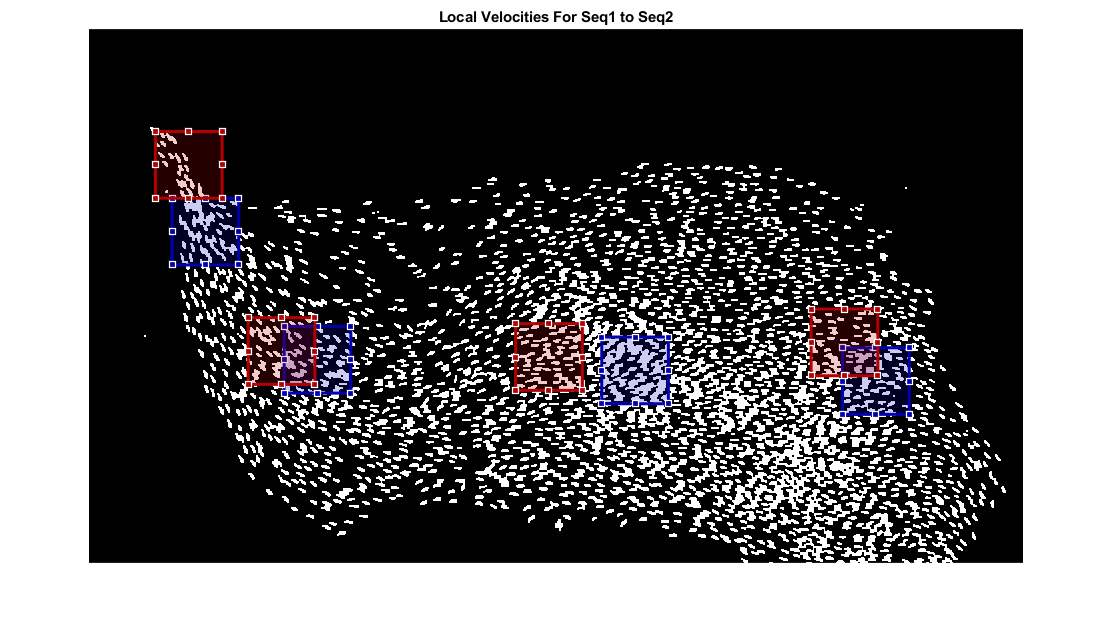

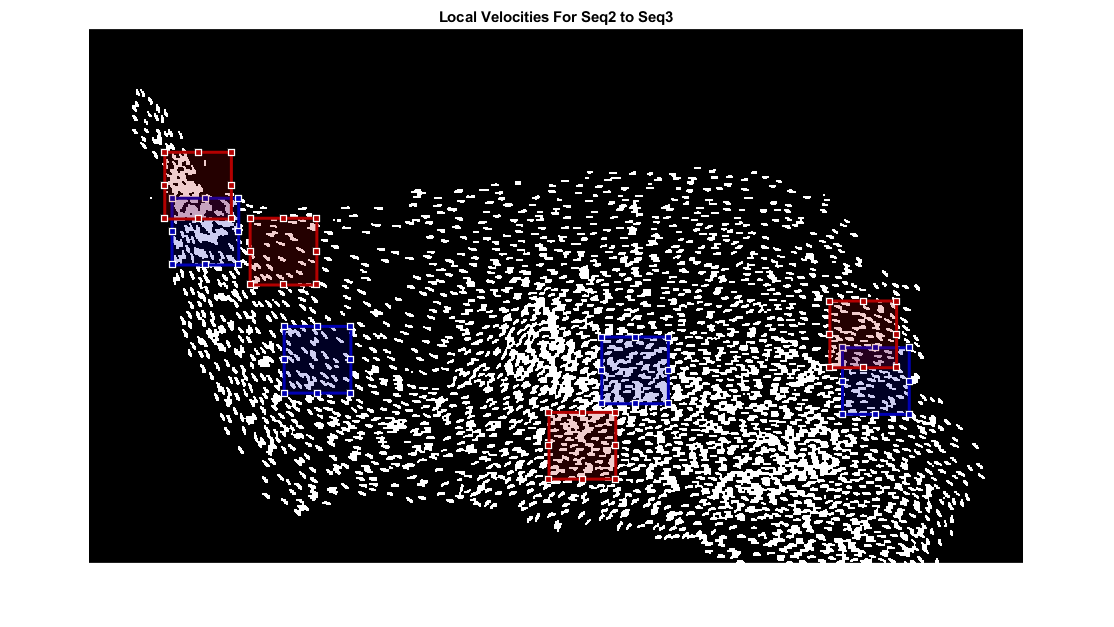

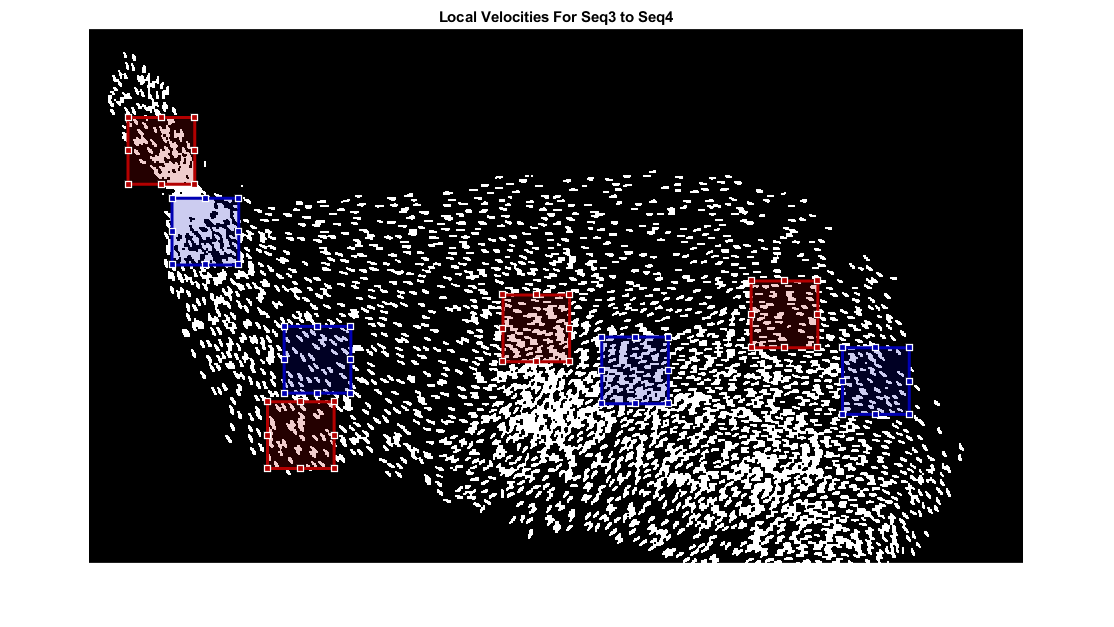

% Combine all 4 sections onto entire frame to visual different movements
% across the various areas and pockets of sheep.
for i = 1:size(dispvel,1)
    figure;
    imshow(imgs{i+1,5});
    for j = 1:size(dispvel,2)
        drawrectangle(gca,'Position',[dispvel{i,j,1},dispvel{i,j,2},boxlen,boxlen],'Color',[0.0,0.0,0.7]);
        drawrectangle(gca,'Position',[dispvel{i,j,3},dispvel{i,j,4},boxlen,boxlen],'Color',[0.7,0.0,0.0]);
    end
    title("Local Velocities For Seq" + string(i) + " to Seq" + string(i+1));
end


% Calculate the displacements of an entire section by averaging the
% displacements of all 4 frames
disp("Start Local Velocity Measurements---------------");

Start Local Velocity Measurements---------------


difftot = zeros(size(dispvel,2),2);
for i = 1:size(dispvel,2)
    disp("Section " + string(i) + " Measurements");
    for j = 1:size(dispvel,1)
        newx = dispvel{j,i,1}-dispvel{j,i,3};
        newy = dispvel{j,i,2}-dispvel{j,i,4};
        difftot(i,1) = difftot(i,1) + newx; % Add new x displacement onto total
        difftot(i,2) = difftot(i,2) + newy; % Add new y displacement onto total
        vals = sqrt(newx^2+newy^2) % Calculate magnitude for each section of each frame
        vala = atan(newy/newx)*180/pi % Calculate angle for each section of each frame
    end
    difftot(i,1) = difftot(i,1)/3; % Calculate average x displacement
    difftot(i,2) = difftot(i,2)/3; % Calculate average y displacement
end

Section 1 Measurements


vals = 103.0776

vala = 75.9638

vals = 69.8713

vala = 80.9421

vals = 137.8296

vala = 61.3895

Section 2 Measurements


vals = 55.5428

vala = 13.5359

vals = 169.8382

vala = 72.5252

vals = 115.7325

vala = -77.5249

Section 3 Measurements


vals = 130.5412

vala = 8.8129

vals = 137.8768

vala = -55.0420

vals = 160.8509

vala = 23.0583

Section 4 Measurements


vals = 74.6525

vala = 50.9806

vals = 72.5328

vala = 74.8142

vals = 169.6143

vala = 36.1267


% Calculate magnitudes and angles for average displacements
disp("Average Measurements");

Average Measurements


magsec1 = sqrt((difftot(1,1))^2+(difftot(1,2))^2)

magsec1 = 102.4717

magsec2 = sqrt((difftot(2,1))^2+(difftot(2,2))^2)

magsec2 = 48.0093

magsec3 = sqrt((difftot(3,1))^2+(difftot(3,2))^2)

magsec3 = 119.0873

magsec4 = sqrt((difftot(4,1))^2+(difftot(4,2))^2)

magsec4 = 101.7584

angsec1 = atan(difftot(1,2)/difftot(1,1))*180/pi

angsec1 = 70.6220

angsec2 = atan(difftot(2,2)/difftot(2,1))*180/pi

angsec2 = 25.4976

angsec3 = atan(difftot(3,2)/difftot(3,1))*180/pi

angsec3 = -4.8169

angsec4 = atan(difftot(4,2)/difftot(4,1))*180/pi

angsec4 = 48.3197

disp("End Local Velocity Measurements------------------");

End Local Velocity Measurements------------------
